# Pareto & MinMax (*Storage based, reformat*)

clear;
rng('default');

## Settings

run('../make_settings("DataType", "condo", "PriceType", "enel").m');
load('../settings.mat');
load('../misc/colors.mat');

### Prices and costs

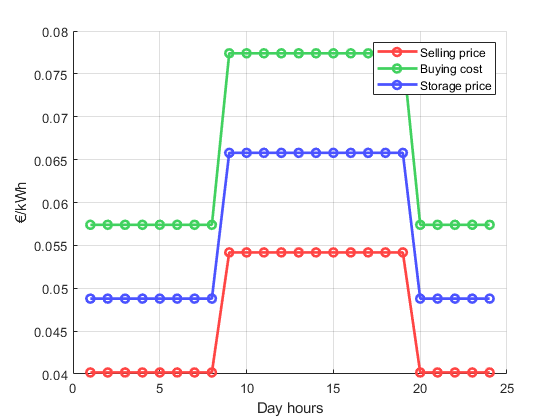

figure
hold on;
plot(R, "-o", "LineWidth", 2, 'Color', retailer_color_rgb); 
plot(C, "-o", "LineWidth", 2, 'Color', prosumer_color_rgb); 
plot(L, "-o", "LineWidth", 2, 'Color', provider_color_rgb); 
grid on;
hold off;
xlabel('Day hours');
ylabel('€/kWh');
legend('Selling price', 'Buying cost', 'Storage price');
hold off;

### Power generation and demand

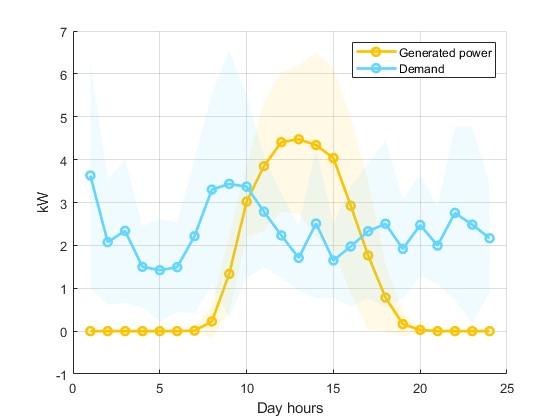

std_PV = std(PV, 0, 1);
std_DP = std(DP, 0, 1);

figure
hold on;
PV_plot = plot(avg_PV, "-o", ...
               "Color", generation_color_rgb, ...
               "LineWidth", 2); 
grid on;
PV_fill = fill([1:T fliplr(1:T)], [avg_PV - std_PV, fliplr(avg_PV + std_PV)], ...
                generation_color_rgb, ...
                'LineStyle', 'none', ...
                'FaceAlpha', 0.1);

DP_plot = plot(avg_DP, "-o", ...
               "Color", demand_color_rgb, ...
               "LineWidth", 2);
grid on;
DP_fill = fill([1:T fliplr(1:T)], [avg_DP - std_DP, fliplr(avg_DP + std_DP)], ...
                demand_color_rgb, ...
                'LineStyle', 'none', ...
                'FaceAlpha', 0.1);
xlabel('Day hours');
ylabel('kW');
legend([PV_plot, DP_plot], "Generated power", "Demand");
hold off;

## Optimization problem

% Binary masks
M_P = kron(ones(1,5), kron(eye(P), ones(1,T)));
M_S = kron(ones(1,3), kron(eye(S), ones(1,T)));

M = [M_P zeros(P, 3*S*T)
     zeros(S, 5*P*T) M_S];

% Objective matrix F
f_P = [kron(ones(1,P), C) -kron(ones(1,P), R) zeros(1,T*P) zeros(1,T*P) kron(ones(1,P), L)];
f_S = [zeros(1,T*S) zeros(1,T*S) -kron(ones(1,S), L)];
F = [kron(ones(P,1), f_P) zeros(P, 3*S*T);
     zeros(S, 5*P*T) kron(ones(S,1), f_S)].*M;

% Objective matrix H
H_P = diag([kron(csi, ones(1,T)) kron(csi, ones(1,T)) kron(csi, ones(1,T)) kron(csi, ones(1,T)) zeros(1, T*P)]);
H_S = kron([1 1 0; ...
            1 1 0; ...
            0 0 0], diag(kron(zeta, ones(1,T))));
H = [H_P zeros(5*T*P, 3*T*S);
    zeros(3*T*S, 5*T*P) H_S];

% Multiobjective function
mobj = @(x) 0.5*M.*kron(ones(P+S, 1), x)*(H*x') + F*x';

% Equality matrix
k_P = kron(eye(P), [zeros(1,T-1) 1]);
K_P = -eye(T*P) + diag(alpha * ones(1,T*P-1), -1);

K_S = -eye(T*S) + diag(alpha * ones(1,T*S-1), -1);
 
A_1P = [eye(T*P) -eye(T*P) eye(T*P) -eye(T*P) zeros(T*P); 
        zeros(T*P) zeros(T*P) -Eff_dis*eye(T*P) Eff_ch*eye(T*P) K_P; 
        zeros(P,T*P) zeros(P,T*P) zeros(P,T*P) zeros(P,T*P) k_P];

A_1S = [Eff_ch*eye(T*S) -Eff_dis*eye(T*S) K_S];

A_2P = [zeros(T,T*P) zeros(T,T*P) kron(ones(1,P), eye(T)) zeros(T,T*P) zeros(T,T*P);
        zeros(T,T*P) zeros(T,T*P) zeros(T,T*P) kron(ones(1,P), eye(T)) zeros(T,T*P)];

A_2S = [zeros(T,T*S) -kron(ones(1,S), eye(T)) zeros(T,T*S);
        -kron(ones(1,S), eye(T)) zeros(T,T*S) zeros(T,T*S)];

A = [A_1P zeros(P*(2*T+1), 3*S*T);
     zeros(S*T, 5*P*T) A_1S;
     A_2P A_2S];

% Equality vector
a_P = [reshape(DP' - PV', 1, [])';
       kron(s_init', [-alpha; zeros(T-1,1)]);
       s_init'];

a_S = kron(b_init', [-alpha; zeros(T-1,1)]);

a = [a_P; 
     a_S;
     zeros(2*T,1)];

% Inequality matrix 
B_P = kron([1 0 0 0 0; 
            0 1 0 0 0; 
            0 0 1 0 0; 
            0 0 0 1 0], eye(T*P));

B_S = eye(3*S*T);

B = [B_P zeros(4*T*P, 3*T*S);
     zeros(3*S*T, 5*T*P)  B_S];

% Inequality vector 
b_P = [ones(2*T*P, 1) * p_max;
       ones(2*T*P, 1) * d_max];

b_S = [ones(2*T*S, 1) * q_max;
       kron(b_max', ones(T,1))];

b = [b_P;
     b_S];

% Lower bound vector
l = zeros(1, T*(5*P + 3*S));

% Load the solution from the centralized approach
load('data/centralized.mat', 'x');

### Pareto frontier

% Find the Pareto frontier
options = optimoptions('paretosearch', 'InitialPoints', x);
[fp, pareto_costs] = paretosearch(mobj, 5*P*T + 3*S*T, B, b, A, a, l, [], [], options);

### MinMax

% Find the MinMax solution
[mm, mm_costs] = fminimax(mobj, x', B, b, A, a, l, []);

## Plotting the results

### Min. total cost function VS Individual best payoff

coll_welf_cost = mobj(x');
min_indiv_cost = min(pareto_costs);

figure
bar([coll_welf_cost min_indiv_cost']);
legend('Cost from collective welfare', ...
       'Min cost from Pareto frontier');
xlabel('Prosumers and Providers');
ylabel('€');